1.1 Import images to create decent base-cell

clear

%Every section starts with defining its values. if you keep every variable
%as its default it will all rin in one go but you're also able tro change
%inital values to test specific cases

%Import images to create decent base-cell
myfolder="car/"

myfolder = "car/"

filetype= "*.jpg"; % *.filetype
filepattern = fullfile(myfolder,filetype);
jpegFiles = dir(filepattern);

%different arrays 
myArray = {};
testArray = [];

%read images
for k = 1:length(jpegFiles)
    
    baseFileName = jpegFiles(k).name;
    fullFileName = fullfile(myfolder, baseFileName);
    fprintf(1,"now reading %s\n", fullFileName);
    [imageArray,map,alpha] = imread(fullFileName);
    imageArray = im2double(imageArray);
    imageArray = imresize(imageArray,0.5,"bicubic");
    
    %convert RBG to lab
    lab = rgb2lab(imageArray);
    L = mean2(lab(:,:,1));
    a = mean2(lab(:,:,2));
    b = mean2(lab(:,:,3));
    
    %add cell containing filename, Lab values and the acutal image
    test{k} = {fullFileName,[L,a,b],imageArray};
  
    
    drawnow;
end

now reading car\car_0000.jpg
now reading car\car_0001.jpg
now reading car\car_0002.jpg
now reading car\car_0003.jpg
now reading car\car_0004.jpg
now reading car\car_0005.jpg
now reading car\car_0006.jpg
now reading car\car_0007.jpg
now reading car\car_0008.jpg
now reading car\car_0009.jpg
now reading car\car_0010.jpg
now reading car\car_0011.jpg
now reading car\car_0012.jpg
now reading car\car_0013.jpg
now reading car\car_0014.jpg
now reading car\car_0015.jpg
now reading car\car_0016.jpg
now reading car\car_0017.jpg
now reading car\car_0018.jpg
now reading car\car_0019.jpg
now reading car\car_0020.jpg
now reading car\car_0021.jpg
now reading car\car_0022.jpg
now reading car\car_0023.jpg
now reading car\car_0024.jpg
now reading car\car_0025.jpg
now reading car\car_0026.jpg
now reading car\car_0027.jpg
now reading car\car_0028.jpg
now reading car\car_0029.jpg
now reading car\car_0030.jpg
now reading car\car_0031.jpg
now reading car\car_0032.jpg
now reading car\car_0033.jpg
now reading ca

1.2 Takes the CellArray(test) created in part1.1 and uses K-means to narrow it down to as many colors we choose (50?)

updated, can now use the function KmenasOnCellArra(cellarray, number of clusters) to do this,

% Takes the CellArray created in part1 and uses K-means to narrow it down
% to as many colors we choose (50?)

%%Va inte dum i huvudet, du vet vad du ska göra mvh past tim 
CIDb = test; %default
ArrayOflab = [];
for i=1:length(CIDb)
    labValues = cell2mat(CIDb{i}(2));
    ArrayOflab(i,:) = [labValues(1),labValues(2),labValues(3)];
end


%k-means do split the colors into clusters
[index,C] = kmeans(ArrayOflab,10);
rgbColorsRaw = [];

%displays the colors given from the cluster cores
for i = 1:length(C)
    rgbColorsRaw(i,1:3) = lab2rgb(C(i,1:3));
end



% now we need to connect the ClusterColors to the filenames #profit
cluster = C(1,1:3);
cellmat = cell2mat(CIDb{1}(1,2));
counter = 1;
newDatabase = {};
valueBestMatch=1000; % big number to overwrite
rgbColorsFromMatrix =[];

%Way too complicated than it should be but it works... 
for i = 1:length(C)
    for j =1:length(CIDb)
        cluster = C(i,1:3);
        cellmat = cell2mat(CIDb{j}(1,2));
        %apparently The centroid issnt always a value from the original
        %matrix... 
        deltaE = sqrt((cellmat(1)-cluster(1))^2+(cellmat(2)-cluster(2))^2+(cellmat(3)-cluster(3))^2);
        
         if valueBestMatch>deltaE
            valueBestMatch = deltaE;
            newDatabase{counter} = CIDb{i};
            rgbColorsFromMatrix(counter,1:3) = lab2rgb(cellmat(1,1:3));
         end
        
        
    end
    valueBestMatch = 100;
    counter = counter+1;
end

%%fast test on fuction



%%********REMOVE LATER******** 
% this is just to see the differense between centroids and the value of the
% picture we found closest 
rgbColorsRaw = []


rgbColorsRaw =

     []



justSommeColors = []


justSommeColors =

     []



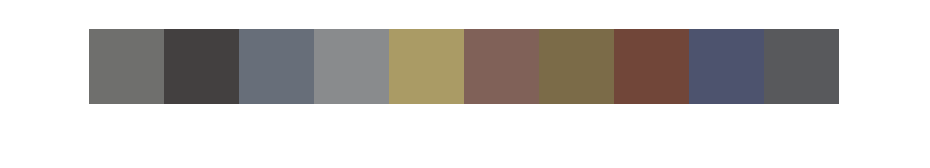


%displays the colors given from the cluster cores
for i = 1:length(C)
    rgbColorsRaw(i,1:3) = lab2rgb(C(i,1:3));
    cellmat = cell2mat(CIDb{i}(1,2));
    %justSommeColors(i,1:3) = lab2rgb(cellmat(1,1:3));
end

showRGB(rgbColorsRaw)

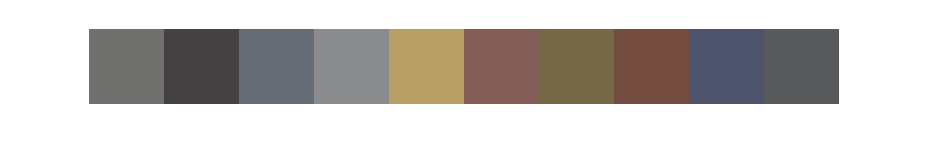

showRGB(rgbColorsFromMatrix)


%Clusters is not the same every iteration which might be a problem but also
%might not

Here we can see how the function performs in several iterations. it's hard to tell if i make any significant diffrense since kmeans returns a little bit diffrent each time... mainly the order

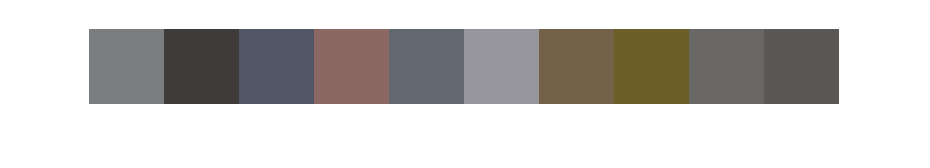

[testFunction,rgb,rawrgb] = KmeansOnCellArray(KmeansOnCellArray(KmeansOnCellArray(test,500),250),10);
showRGB(rgb)

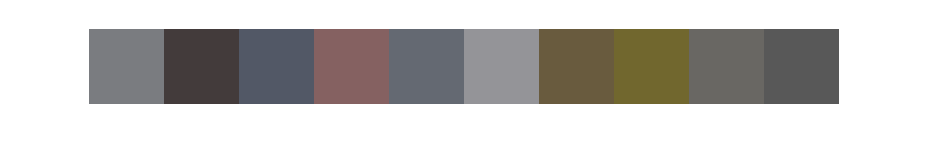

showRGB(rawrgb)

%TESTING

Test bit to evaluate images collerating to matrix

works on a 5x10 matrix

%%newDatabase
% 
% nameArrayForTesting = strings;
% 
% 
% for x = 0:5
%     for y = 1:10
%         %%fixa den här loopen, borde inte vara svårt 
%             nameArrayForTesting(1+x,y)=string(newDatabase{1+(x*5)+y}(1));
%     end
%     
% end

Index exceeds the number of array elements (10).

% 
% Repoduced = [];
% nameArrayToReprocude = nameArrayForTesting; %Default
% 
% 
% 
% 
% [row,col] = size(nameArrayToReprocude);
% for i=1:row
%     for j=1:col
%         
%         current = imread(nameArrayToReprocude(i,j)); %Read img
%         current = im2double(current); %make double
%         
%         current = imresize(current,0.25,"bicubic"); %resize according to first step
%         Repoduced((i-1)*length(current)+1:i*length(current), (j-1)*length(current)+1:j*length(current), :) = current; %replace "namepixel" with image
%         
%     end
% end
% imshow(imresize(Repoduced,3,"bicubic"))



1.3 Create Array consisting of name representing each pixel

CurrentImageDatabase is the imagedatabase you want to use

pictureToReproduce is the images you want to reproduce

% New section to use the base-cell

%read the img to be reproduced
%default CurrentImageDatabase = test %full database
CurrentImageDatabase = newDatabase; %This is where we specifie which imagedatabase we're using from part 1
pictureToReproduce = im2double(imread("car_0000.jpg")); %choose image to reproduce
%short test to see all individual images

imshow(pictureToReproduce);
ImgToRepLab = rgb2lab(pictureToReproduce);
ImageNameArray = strings;


%%start high coz we want low
valueBestMatch = 100;
nameOfBestMatch  ="";

%so we can handle different sized images
size(ImgToRepLab);
[row,col,dontCare] = size(ImgToRepLab);

%largest fucking forloop in my life
for i = 1:row %x img
    for j= 1:col% y img
        for k = 1:length(CurrentImageDatabase)% array with all img
            %extract the lab values from Cell
            labValues = cell2mat(CurrentImageDatabase{k}(2));
            deltaE = sqrt((ImgToRepLab(i,j,1)-labValues(1))^2+(ImgToRepLab(i,j,2)-labValues(2))^2+(ImgToRepLab(i,j,3)-labValues(3))^2);
            
                if valueBestMatch>deltaE
                    valueBestMatch = deltaE;
                    nameOfBestMatch = string(CurrentImageDatabase{k}(1));
                end
            %sqrt(ImgToRepLab(i,j,1)-test{k})
            
            
        end
        nameOfBestMatch;
        % creating NameArray where each "pixel" corresponds to the name of a picture in
        % the cell-database
        ImageNameArray(i,j) = nameOfBestMatch;
        valueBestMatch=100;
    end
end

1.4 Reconstruct image from NameArray

nameArrayToReproduce is the namearray constructed in 1.3

%NameArray2Img
Repoduced = []
nameArrayToReprocude = ImageNameArray; %Default




[row,col] = size(nameArrayToReprocude);
for i=1:row
    for j=1:col
        
        current = imread(nameArrayToReprocude(i,j)); %Read img
        current = im2double(current); %make double
        
        current = imresize(current,0.25,"bicubic"); %resize according to first step
        Repoduced((i-1)*length(current)+1:i*length(current), (j-1)*length(current)+1:j*length(current), :) = current; %replace "namepixel" with image
        
    end
end
imshow(Repoduced)

imwrite(Repoduced,'Carcus.jpeg','JPEG');
